# **Example: Deep Neural Network-Based Approximation of Nonlinear Model Predictive Control: Applications to Truck-Trailer Control Systemd**

**Date: **25.06.24

**Corresponding Author: **Kyoungseok Han (kyoungsh@hanyang.ac.kr), Hanyang University

**Author: **Suyong Park (suyongpark@hanyang.ac.kr), Hanyang University

**Description: **This script implements a closed-loop MPC controller for a truck-trailer vehicle following a reference path. The controller minimizes tracking errors while respecting physical constraints. If you find this code helpful, we kindly ask that you cite the following reference: [**https://link.springer.com/article/10.1007/s12555-024-0475-2**](https://link.springer.com/article/10.1007/s12555-024-0475-2)

**Requirements:**

- MATLAB R2020b or later

- Acados toolbox ([https://docs.acados.org/list_of_projects/index.html](https://docs.acados.org/list_of_projects/index.html))

- CMake ([https://cmake.org/download/](https://cmake.org/download/))

- MinGW-w64 (MATLAB add-on)

# **STEP2: Collection of data for approximating NMPC**

In STEP 2, data is collected for all possible poses of the truck-trailer to approximate the NMPC. The data collection procedure for forward motion is carried out using **implicit NMPC (step1)**. Our approach to approximating NMPC focuses on learning all potential TT poses within a constrained state space for path tracking.

clear all; clc;

delete template...
done.
delete template...
done.


% History 
x0_history = [];
optimal_u_history =[];

## Define parameters

We specify the initial states of the truck trailer for the learning process. The initial state for learning in forward motion is $\left\lbrace \theta_{\textrm{hf}} ,\theta_{\textrm{tf}} ,e_{f,h} \right\rbrace$ and refmaned of state can be calcuated. The range of the initial state for forward motion learning can be defined as:


$$\begin{array}{l}
\theta_{\textrm{hf},\min } \le \theta_{\textrm{hf}} \le \theta_{\textrm{hf},\max } \\
\theta_{\textrm{hf}} +\theta_{\textrm{tf},\min } \le \theta_{\textrm{tf}} \le \theta_{\textrm{hf}} +\theta_{\textrm{tf},\max } \\
e_{f,h,\min } \le e_{f,h} \le e_{f,h,\max } 
\end{array}$$


where $\theta_{\textrm{hf}}$ is angle between head-truck and reference path,$\theta_{\textrm{tf}}$ is angle between trailer and reference path and $e_{f,h}$ is distance error between head-truck and reference path. We divide the range of essential initial states into a grid to cover the required initial state space. Each initial state is divided into 25 intervals ($n_d =25\;\mathrm{x}\;\textrm{25}\;\mathrm{x}\;25$).

%%========Simulation parameters===========%%
v_h = 5; % nominal velocity [m/s]
h = 0.1; % sampling time = length of first shooting interval
N_sim = 200; % simulation time: N_sim * h
lt = 10;

%%========Cost weights===========%%
W_x = diag([0, 0, 0, 0, 0, 0, 1e3, 1e-3, 1e-2, 0, 0, 0]); % state weights
W_u = 1000; % input weight

%%========Constraints===========%%
delta_max = pi/5; % maximum steering angle [rad]

%%========Number of state gird for data collection===============%%
N_grid = 25;        % the number of grid

%%========Define state constraint for collection of data========%%
% Select grid state
theta_hf0_grid = linspace(-pi/2,pi/2,N_grid);
e_h0_grid = linspace(-12,12,N_grid);

## Define Initial State 

 Data is collected for both forward motion by solving the implicit NMPC problem. According to mode selection, such as forward and backward, the initial state ${\mathbf{x}}_0$ is chosen to define the initial truck-trailer pose.Then, NMPC solves the formulated problem at the initial time step to obtain a pair of data sets. The computed input values $u\left(0:N-1\right)$ are stored along with their corresponding state ${\mathbf{x}}_0$, where N is prediction horizon of NMPC. The procedure for collecting data is repeated until the required amount of data, $n_d$ ,is satisfied.

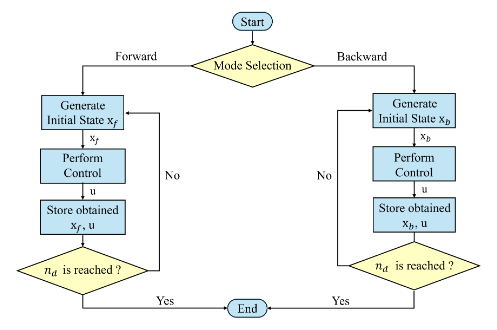

[Data collection procedure]

for i = 1:1:N_grid
    for j = 1:1:N_grid
        for k = 1:1:N_grid
clear functions
%Initial state
% States = {'x_h [m]', 'y_h [m]', '\theta_{hf} [rad]', 'x_t [m]', 'y_t [m]', '\theta_{tf} [rad]', ...
%          'e_h [m]', 'e_{\theta,hp} [rad]', 'e_{\theta,ht} [rad]', 'e_t [m]', 'e_{\theta,tp} [rad]', 'e_{\theta,th} [rad]'};
x_h0 = 0;
y_h0 = 0;
theta_hf0 = theta_hf0_grid(i);

theta_tf0_grid = linspace(-pi/3+theta_hf0,pi/3+theta_hf0,N_grid);
theta_tf0 = theta_tf0_grid(j);

e_h0 = e_h0_grid(k);
x_t0 = x_h0-lt*cos(theta_tf0);
y_t0 = y_h0-lt*sin(theta_tf0);
e_theta_h0 = theta_hf0;
e_theta_ht0 = theta_hf0-theta_tf0;
e_t0 = e_h0-lt*sin(theta_tf0);
e_theta_t0 = theta_tf0;          

% initial state
x0 = [x_h0;y_h0;theta_hf0;x_t0;y_t0;theta_tf0;e_h0;e_theta_h0;e_theta_ht0;e_t0;e_theta_t0;e_theta_ht0]; 
x0_history = [x0_history ,x0]

## Initialization

To initialize shooting method, we refered example: C:\Users\user\acados\examples\acados_matlab_octave\pendulum_on_cart_model

Detailed description can be found: [https://docs.acados.org/list_of_projects/index.html](https://docs.acados.org/list_of_projects/index.html)

% check acados requirements
check_acados_requirements()

%% OCP DESCRIPTION
ocp = AcadosOcp();

%% IVP DESCRIPTION
sim = AcadosSim();

%% SOLVER OPTIONS

%% discretization
N = 20;  % number of shooting intervals

% nonuniform discretization
shooting_nodes = [0.0 0.01, 0.05*(1:N-1)];
T = shooting_nodes(end);

ocp.solver_options.tf = T;
ocp.solver_options.N_horizon = N;
ocp.solver_options.shooting_nodes = shooting_nodes;
ocp.solver_options.nlp_solver_type = 'SQP';
ocp.solver_options.qp_solver = 'PARTIAL_CONDENSING_HPIPM';
ocp.solver_options.qp_solver_cond_N = 5; % for partial condensing
ocp.solver_options.globalization = 'MERIT_BACKTRACKING'; % turns on globalization

% Solver tolerance settings for smoother control
ocp.solver_options.nlp_solver_max_iter = 100;
ocp.solver_options.qp_solver_iter_max = 100;
ocp.solver_options.nlp_solver_tol_stat = 1e-6;
ocp.solver_options.nlp_solver_tol_eq = 1e-6;
ocp.solver_options.nlp_solver_tol_ineq = 1e-6;

% we add some model-plant mismatch by choosing different integration
% methods for model (within the OCP) and plant:

% integrator model
model_integrator_type = 'ERK';
model_sim_method_num_stages = 1;
model_sim_method_num_steps = 2;

ocp.solver_options.sim_method_num_stages = model_sim_method_num_stages;
ocp.solver_options.sim_method_num_steps = model_sim_method_num_steps;
ocp.solver_options.integrator_type = model_integrator_type;

% integrator plant
plant_integrator_type = 'IRK';
plant_sim_method_num_stages = 3;
plant_sim_method_num_steps = 3;

sim.solver_options.num_stages = model_sim_method_num_stages;
sim.solver_options.num_steps = model_sim_method_num_steps;
sim.solver_options.Tsim = h;
sim.solver_options.integrator_type = model_integrator_type;

%% MODEL with velocity as parameter
model = forward_motion_model_v2(h,true);
ocp.model = model;
sim.model = model;

% dimensions
nx = model.x.rows();
nu = model.u.rows();

%% COST: nonlinear-least squares cost - MODIFIED to include control penalty
ocp.cost.cost_type_0 = 'NONLINEAR_LS';
ocp.cost.cost_type = 'NONLINEAR_LS';
ocp.cost.cost_type_e = 'NONLINEAR_LS';


% Cost expressions - INCLUDING control input for all stages except terminal
model.cost_y_expr_0 = vertcat(model.x, model.u);  % Stage 0: states + control (dimension: nx + nu)
model.cost_y_expr = vertcat(model.x, model.u);    % Intermediate stages: states + control (dimension: nx + nu)
model.cost_y_expr_e = model.x;                    % Terminal stage: only states (dimension: nx)

% Weight matrices - Including control penalty
W_combined = blkdiag(W_x, W_u);                   % Combined weight matrix
ocp.cost.W_0 = W_combined;                        % Weight matrix for stage 0 (nx+nu x nx+nu)
ocp.cost.W = W_combined;                          % Weight matrix for intermediate stages (nx+nu x nx+nu)
ocp.cost.W_e = W_x;                               % Weight matrix for terminal stage (nx x nx)

% Initialize references - States + control references
% Control reference is set to 0 (minimize control effort)
ocp.cost.yref_0 = zeros(nx + nu, 1);             % Reference for stage 0 (dimension: nx + nu)
ocp.cost.yref = zeros(nx + nu, 1);               % Reference for intermediate stages (dimension: nx + nu)
ocp.cost.yref_e = zeros(nx, 1);                  % Reference for terminal stage (dimension: nx)

%% CONSTRAINTS
ocp.constraints.constr_type = 'AUTO';
ocp.constraints.constr_type_0 = 'AUTO';

model.con_h_expr_0 = model.u;
ocp.constraints.lh_0 = -delta_max;
ocp.constraints.uh_0 = delta_max;

model.con_h_expr = model.u;
ocp.constraints.lh = -delta_max;
ocp.constraints.uh = delta_max;

% Optional: Add rate constraints for smoother control
% This would require augmenting the state with previous control input
% For now, we rely on the cost function penalty

ocp.constraints.x0 = x0;

%% OCP SOLVER
ocp_solver = AcadosOcpSolver(ocp);

## Simulation Setting

This section is setting simulation for solver and intergrator(model & plant). Also, reference vector is initilized for tracking zero-error state. 

% set parameter for all stages (velocity)
for z = 0:N
    ocp_solver.set('p', v_h, z);
end

%% SIM SOLVER/INTEGRATOR
sim_solver = AcadosSimSolver(sim);
% set parameter (slight model-plant mismatch)
sim_solver.set('p', v_h * 1); % 2% velocity mismatch

% preallocate memory
x_sim = zeros(nx, N_sim+1);
u_sim = zeros(nu, N_sim);

x_sim(:,1) = x0;

% Initialize reference vectors
yref_0 = zeros(nx + nu, 1);                       % Stage 0 reference (dimension: nx + nu)
yref = zeros(nx + nu, 1);                         % Intermediate stages reference (dimension: nx + nu)  
yref_e = zeros(nx, 1);                            % Terminal stage reference (dimension: nx)

## Simulation

This section presents a simulation of a truck-trailer system in forward motion. The system is designed to follow a reference path while minimizing the tracking error throughout the simulation.

for z=1:N_sim
    % update initial state
    x0 = x_sim(:,z);
    ocp_solver.set('constr_x0', x0);

    % set references for all shooting nodes
    ocp_solver.set('cost_y_ref', yref_0, 0);       % Stage 0 reference
    for m=1:N-1 % intermediate stages
        ocp_solver.set('cost_y_ref', yref, m);
    end
    ocp_solver.set('cost_y_ref_e', yref_e, N);     % terminal stage

    % solve
    ocp_solver.solve();

    % get solution
    u0 = ocp_solver.get('u', 0);
    status = ocp_solver.get('status'); % 0 - success
     
    % Store both original and filtered control
    u_sim(:,z) = u0;
   
    % simulate one step
    x_sim(:,z+1) = sim_solver.simulate(x0, u0);

    % save input history
    for m=0:N-1
    u_mpc(m+1,z) =  ocp_solver.get('u', m);
    end
end
optimal_u_history = [optimal_u_history, u_mpc(:,1)];

## Collection State

During data collection, the initial state and the control input obtained from NMPC are stored in a `.mat` file at each time step. Based on Ngrid=25, the data collection process is completed after $n_d =25\;\mathrm{x}\;\textrm{25}\;\mathrm{x}\;25$ = 15625 steps.

%% collection state
i=i
j=j
k=k
data_number = i*j*k
save('training_para.mat','optimal_u_history','x0_history','i','j','k')
        end 
    end     
end